**Laboratorium 8 – Sygnały Cyfrowe**

**Jakub Szczypek nr 405912**

**grupa 5 WEAIiIB air**

Zadanie 2

Skok jednostkowy w punktach n = 0 i n = 3

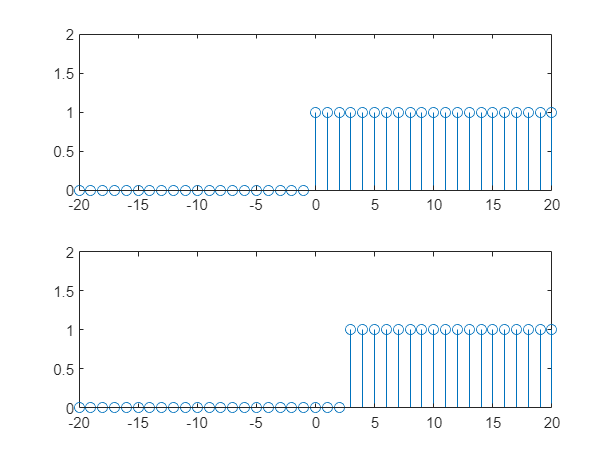

clear all, close all
n=-20:20;
zero = 1-n(1);

x1=zeros(1,length(n));
x1(zero:end)=ones(1);
subplot(2,1,1), 
stem(n,x1), 
axis([-20 20 0 2])

k = zero + 3;
x2 = zeros(1,length(n));
x2(k:end)=ones(1);
subplot(2,1,2), 
stem(n,x2), 
axis([-20 20 0 2])

Zadanie 3

Delta Kroneckera w punkcie n = 0 i n =3

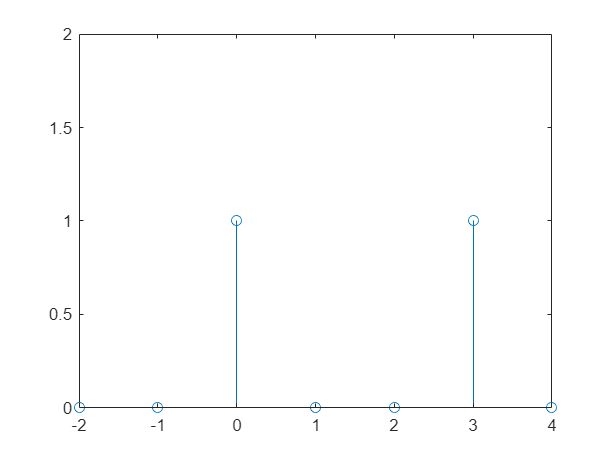

clear all, close all
n = -2:4;
y = [0, 0, 1, 0, 0, 1, 0];
stem(n, y);
axis([-2 4 0 2])

Zadanie 4

Odjęcie od siebie skoku jednostkowego w punkcie 0 oraz przesuniętego w czasie (n=5) daje w rezultacie prostokąt o długości 5 próbek.

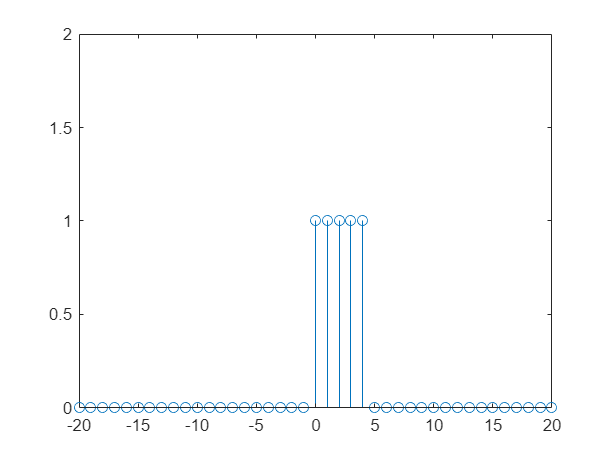

clear all, close all
n=-20:20;
zero = 1-n(1);

x1=zeros(1,length(n));
x1(zero:end)=ones(1);
k = zero + 5;
x2 = zeros(1,length(n));
x2(k:end)=ones(1);

x = x1-x2;
stem(n,x), axis([-20 20 0 2])

Zadanie 5

Większa częstotliwość próbkowania przekłada się na większą rozdzielczość (dokładniejszy obraz) próbkowanego sygnału. Przykład przedstawia funkcję sinus w postaci dwóch przebiegów. Przebieg drugi ma 10x większą częstotliwość próbkowania od pierwszego.

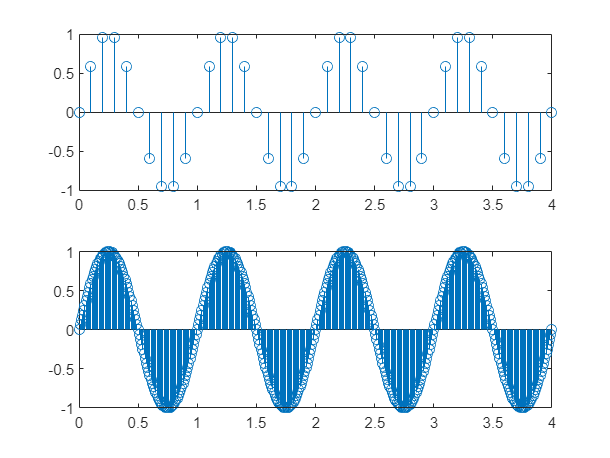

clear all, close all
t1=0:0.1:4;
t2=0:0.01:4;
y1 = sin(2*pi*t1);
y2 = sin(2*pi*t2);
subplot(2,1,1), stem(t1, y1);
subplot(2,1,2), stem(t2, y2);

Zadanie 6

W tym zadaniu tak jak w poprzednim 10x większa liczba próbek daje dokładniejszy obraz.

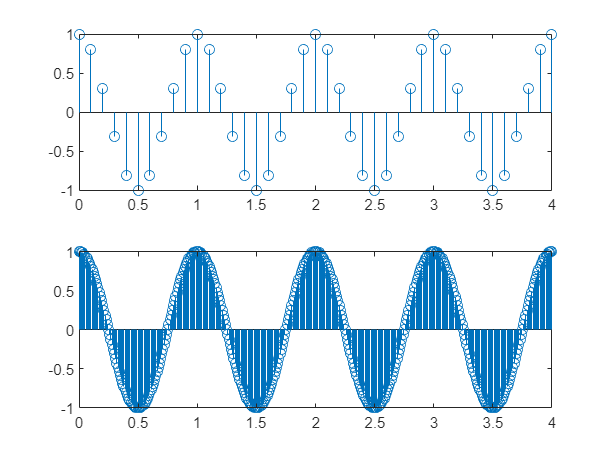

clear all, close all
t1=0:0.1:4;
t2=0:0.01:4;
y1 = cos(2*pi*t1);
y2 = cos(2*pi*t2);
subplot(2,1,1), stem(t1, y1);
subplot(2,1,2), stem(t2, y2);

Zadanie 7

Dyskretna krzywa Gaussa

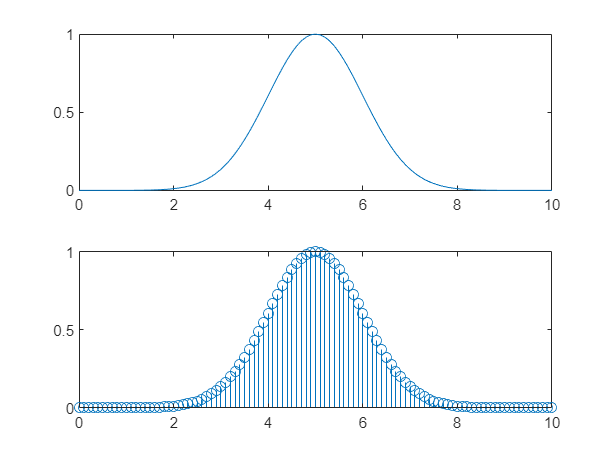

clear all, close all
t = 0:0.1:10;
y = gaussmf(t,[1 5]);
subplot(2,1,1), plot(t, y)
subplot(2,1,2), stem(t, y);

Zadanie 8

Pomnożenie przez siebie dwóch sygnałów y1 i y2 za pomocą mnożenia " .* "

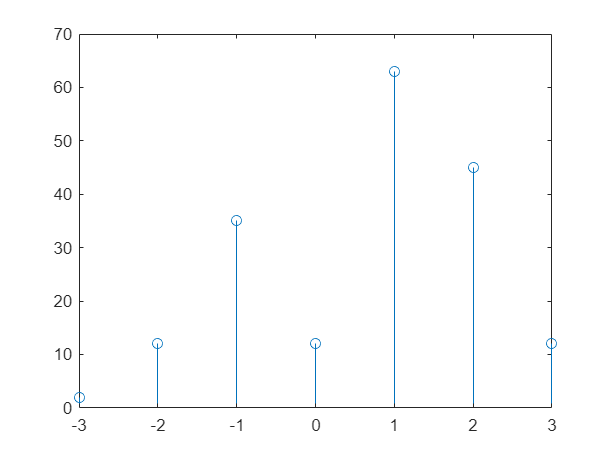

clear all, close all
n=-3:3;
y1=[1,3,5,6,7,9,2]; 
y2=[2,4,7,2,9,5,6];
y3 = y1.*y2;
stem(n, y3)
axis([-3 3 0 70])

Zadanie 9

Odpowiedź impulsowa dla n=0:20 wyrażona następującym wzorem: x(n)=y(n)-0.5y(n-1)+0.7y(n-2).

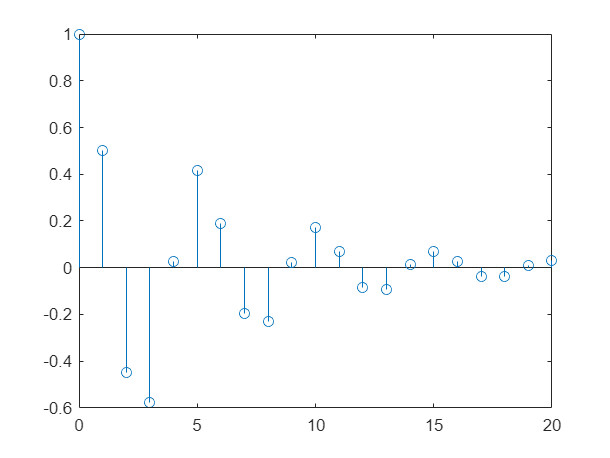

clear all, close all
n=0:20;
x=[1,zeros(1,20)];
a=[1];
b=[1 -0.5 0.7];
y=filter(a,b,x);
stem(n,y)

Zadanie 10

Sygnał sinusoidalny z liczbą próbek n=128, t=k/128, k=0:n; Amplitudą A=1 i częstotliwością podstawową f0=2, p=0, y=A*sin((2*pi*f0*t)+p).

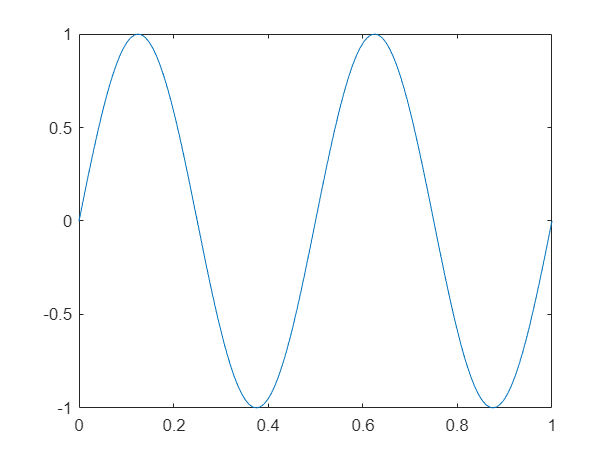

clear all, close all
n = 128;
k = 0:n;
t = k/128;
A = 1;
f0 = 2;
p = 0;
y=A*sin((2*pi*f0*t)+p);
plot(t, y)

Zadanie 11

Sygnał sinusoidalny z liczbą próbek n=128, t=k/128, k=0:n; Amplitudą A=1 i częstotliwością podstawową f0=5, p=0, y=A*sin((2*pi*f0*t)+p). 

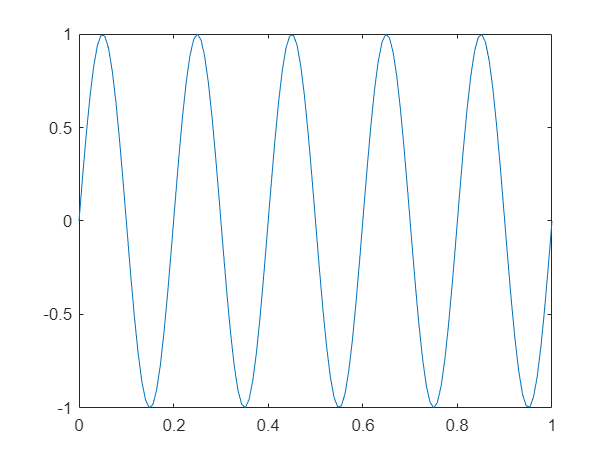

clear all, close all
n = 128;
k = 0:n;
t = k/128;
A = 1;
f0 = 5;
p = 0;
y=A*sin((2*pi*f0*t)+p);
plot(t, y)

Zadanie 12

Generowanie wykresu piłokrztałtnego dla częstotliwości próbkowania fs = 100. 

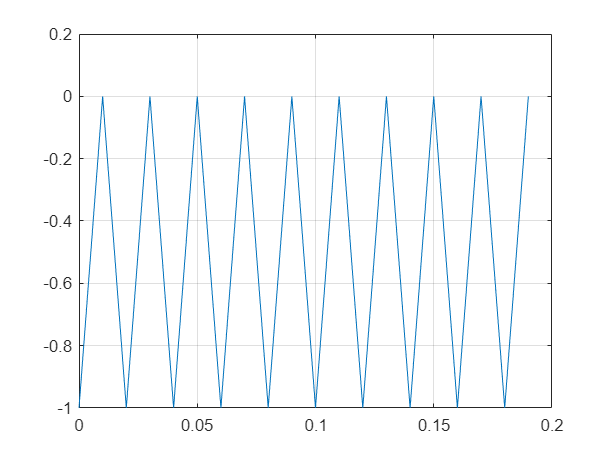

clear all, close all
T = 10*(1/50);
fs = 100;
t = 0:1/fs:T-1/fs;
x = sawtooth(2*pi*50*t);
plot(t,x)
grid on 

Zadanie 13

Generowanie wykresu prostokątnego dla częstotliwości próbkowania fs = 500.

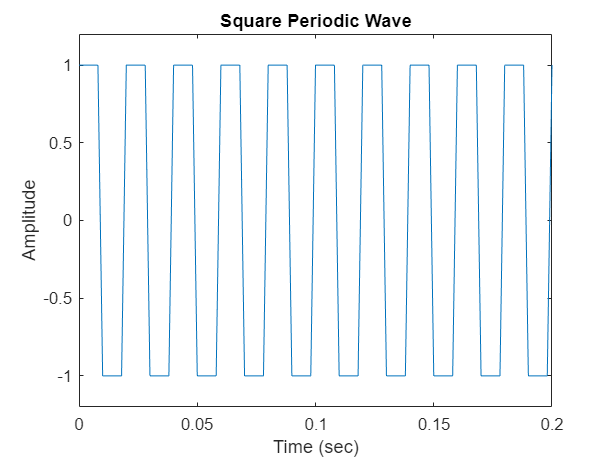

fs = 500;
t = 0:1/fs:1.5;
x2 = square(2*pi*50*t);
plot(t,x2)
axis([0 0.2 -1.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')
title('Square Periodic Wave')

Zadanie 14

Generowanie impulsu trójkątnego i prostokątnego  o szerokości 0.08.

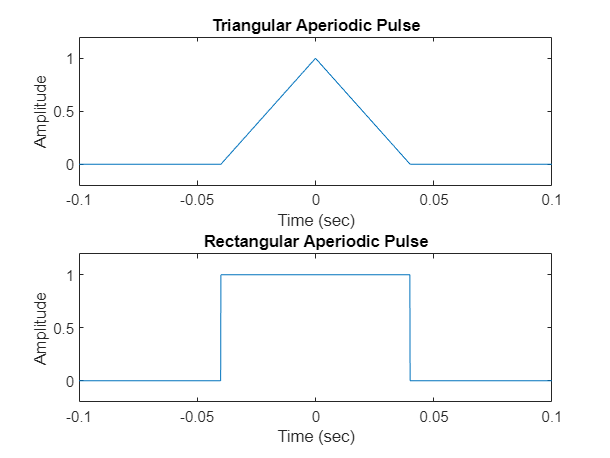

fs = 10000;
t = -1:1/fs:1;
x1 = tripuls(t, 0.08);
x2 = rectpuls(t, 0.08);
subplot(2,1,1)
plot(t,x1)
axis([-0.1 0.1 -0.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')
title('Triangular Aperiodic Pulse')
subplot(2,1,2)
plot(t,x2)
axis([-0.1 0.1 -0.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')
title('Rectangular Aperiodic Pulse') 

**Pytania**

**1. W jaki sposób reprezentujemy sygnały cyfrowe na komputerze i w Matlabie? **

Sygnały cyfrowe są reprezentowane w postaci wektora liczb, którego indeksy są numerami kolejnych próbek. Można je powiązać np. z dyskretnymi chwilami czasu.

**2. Jakie informacje może zawierać sygnał cyfrowy? Wymienić jakieś przykłady? **

Sygnał cyfrowy może reprezentować właściwie dowolną mierzalną wielkość, np. temperaturę, położenie, wilgotność, natężenie światła, stężenie dwutlenku węgla, napięcie elektryczne, natężenie dźwięku, ciśnienie itd.

**3. Czy Pana/Pani zdaniem da się zamienić sygnały cyfrowe na sygnały analogowe? **

Tak, matematycznie wykorzystuje się algorytmy interpolacji. Fizycznie zaś istnieją przetworniki cyfrowo-analogowe (C/A, DAC), które służą do zamiany sygnału cyfrowego na analogowy (najczęściej napięcie).

**4. Na czym polega różnica pomiędzy przekazem analogowym a cyfrowym w telewizji? **

Wygnał analogowy jest o wiele mniej odporny na zakłócenia niż sygnał cyfrowy, na którego jakość wahania  napięcia nie mają wpływu. Współcześnie telekomunikacja i elektronika powszechnego użytku prawie całkowicie została zdominowana przez cyfrowe przetwarzanie sygnałów, które jest powtarzalne, bardziej niezawdone i tańsze od przetwarzania analogowego.

**5.  Czy sygnał cyfrowy może mieć wiele wymiarów? **

Wielowymiarowe sygnały występują w procsach szybkozmiennych o dużej zawartości inforamcyjnej (najczęściej o charakterze oscylacyjnym i dużej ilości zmian w jednostce czasu, co powoduje, że ilość zawartych informacji jest duża).

**6. Czy częstotliwość próbkowania jest ważna? **

Tak w wielu przypadkach dzięki wyższej częstotliwości otrzymujemy wyższą rozdzielczość, a co za tym idzie dokładniejszy obraz sygnału.